## Plots of fixation change per object

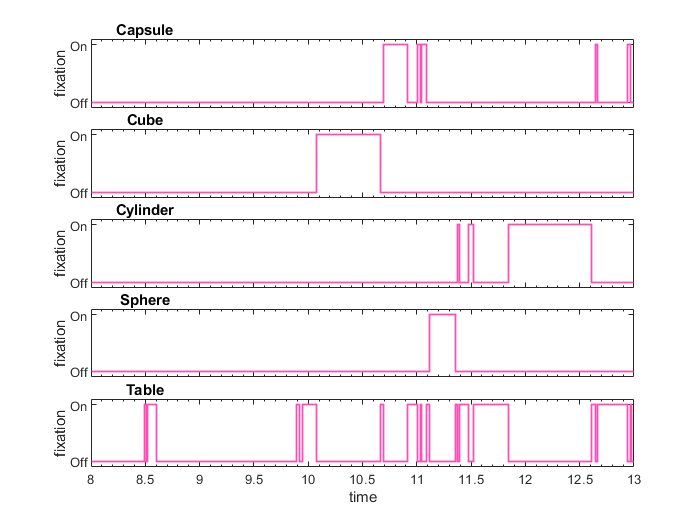

warning('off', 'all')
fc_full = readtable('Focus_Change.csv');
warning('on', 'all')
objectIDs = unique(fc_full.Object);
minx = floor(min(fc_full.Time));
maxx = ceil(max(fc_full.Time));
tiledlayout(length(objectIDs),1);
for i = 1:length(objectIDs)-1
    temp = fc_full(strcmp(fc_full.Object,objectIDs(i,1)),:);
    tempTime = [minx; temp.Time;maxx];
    tempFocus = [0;temp.FocusOn_Off;0];
    nexttile
    stairs(tempTime, tempFocus, 'LineWidth', 1, "Color",[1 0.3 0.7])     
    set(gca, "XLabel",[],'XTickLabel',[],'XMinorTick',"on",'XLim',[minx maxx],...
        "ytick",[0 1],'YTickLabel',{'Off', 'On'},'YLim',[-0.1 1.1])
    ylabel('fixation')
    title(objectIDs(i,1), 'units', 'normalized', 'position', [0.1 1])    
end
i = length(objectIDs);
temp = fc_full(strcmp(fc_full.Object,objectIDs(i,1)),:);
    tempTime = [minx; temp.Time;maxx];
    tempFocus = [0;temp.FocusOn_Off;0];
    nexttile
    stairs(tempTime, tempFocus, 'LineWidth', 1, "Color",[1 0.3 0.7])
    set(gca, 'XMinorTick',"on",'XLim',[minx maxx],...
        'Ytick',[0 1],'YTickLabel',{'Off', 'On'},'YLim',[-0.1 1.1])
    xlabel('time')
    ylabel('fixation')
    title(objectIDs(i,1), 'units', 'normalized', 'position', [0.1 1])
    hold off

    fixationData = zeros(height(fc_full),length(objectIDs));
    fixVariableNames = {'Fixation Count', 'Av. Fix. Duration', ...
        'Total Fix. Duration','Proportion of fixations'};
    fixationVariables = zeros(length(fixVariableNames),length(objectIDs));
    fixationCount = zeros(1,length(objectIDs));
    avFixDuration = zeros(1,length(objectIDs));
    totalFixDuration = zeros(1,length(objectIDs));
    m = zeros(length(fixationData),1);
    for i = 1:length(objectIDs)
        temp = fc_full(strcmp(fc_full.Object,objectIDs(i,1)),:);        
        for j = 1:2:height(temp)
            fixationData(j,i) = temp.Time(j+1)-temp.Time(j);            
        end
        temp2 = fixationData(:,i);
        l = temp2>0;        
        fixationVariables(1,i) = size(temp2(l),1);
        fixationVariables(2,i) = mean(temp2(l));
        fixationVariables(3,i) = sum (temp2(l));        
    end
    for i = 1:length(objectIDs)
        fixationVariables(4,i) = fixationVariables(1,i)/...
            sum(fixationVariables(1,:));
    end
    fixationVariables = array2table(fixationVariables);
    fixationVariables.Properties.VariableNames = objectIDs;
    fixationVariables.Properties.RowNames = fixVariableNames;
    fixationVariables

fixationVariables = 4×5 table
                               Capsule      Cube      Cylinder     Sphere      Table  
                               _______    ________    ________    ________    ________

    Fixation Count                   5           1          3            1          14
    Av. Fix. Duration          0.06682     0.58902    0.27388      0.23435    0.084812
    Total Fix. Duration         0.3341     0.58902    0.82163      0.23435      1.1874
    Proportion of fixations    0.20833    0.041667      0.125     0.041667     0.58333


    %need to eventually format fixationVariables to leave rows for
    %participants

## Heatmap of fixation point

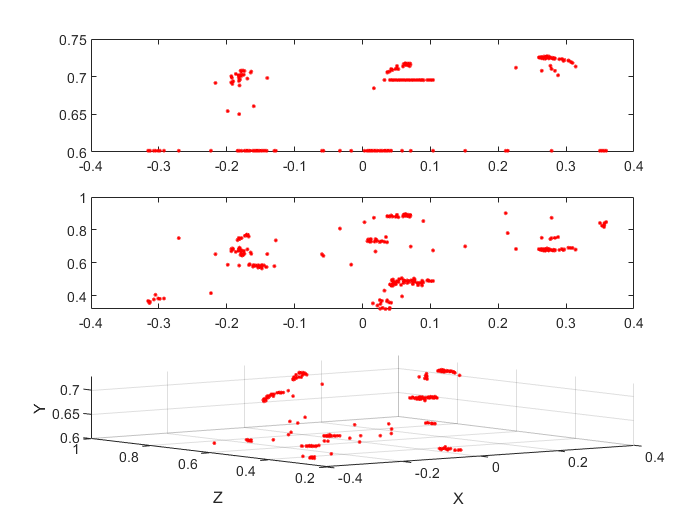

warning('off', 'all')
fp_full = readtable('Fixation_Point.csv');
warning('on', 'all')
tiledlayout(3,1)
nexttile
plot(fp_full.X, fp_full.Y,'.r')
nexttile
plot(fp_full.X, fp_full.Z,'.r')
nexttile
plot3(fp_full.X, fp_full.Z,fp_full.Y,'.r')
xlabel('X')
ylabel('Z')
zlabel('Y')
grid on